# N-R法潮流计算

## 初始化数据

clc,clear
base_MVA = 100.0; %基准容量
error_tol = 0.00001; %误差精度
circle_count = 0; %循环次数


% Bus
% 1.节点号bus number 2.节点类型type 3.发电机功率 4.负荷功率
% 5.电压初始值 6.PV节点电压给定值
% 节点类型标号：1为PQ节点、2为PV节点，3为平衡节点
% 发电机、负荷功率为有名值、电压初始值为标幺值
% Branch
% 1.支路首端编号 2.支路末端编号 3.支路阻抗

% 两个矩阵都已经放入到对应的mat文件里了
% 接线1   对应plan3.PWB
% load plan3.mat 
% %接线2    对应plan4.PWB
load plan4.mat
%下面数据可以同时在PQ和NR法成功收敛
% load success_data.mat

slack_bus_voltage = 1.05; %平衡节点电压幅值
slack_bus_ang = 0; %平衡节点电压相角
%节点数
node_num = size(Bus,1); 
% 电压最终值直角坐标系表达式
u = zeros(node_num,1);
% 电压最终值极坐标系表达式
u_amp = zeros(node_num,1);
u_ang = zeros(node_num,1);
% 节点功率最终值
S= [];
% 节点功率
S_node = zeros(node_num,1);
% 节点电流
I = zeros(node_num,node_num);

## 求节点导纳矩阵

Y = zeros(node_num,node_num);
for i = 1:size(Branch,1)
    p = Branch(i,1);
    q = Branch(i,2);
    node_data_y = 1 ./ Branch(i,3);
    % 修改节点自导纳
    Y(p,p) = Y(p,p) + node_data_y;
    % 修改连接节点自导纳
    Y(q,q) = Y(q,q) + node_data_y;
    % 修改互导纳
    Y(p,q) = Y(p,q) - node_data_y;
    Y(q,p) = Y(p,q);
end
%分解出导纳矩阵的实部和虚部
G = real(Y);
B = imag(Y);

## 读取数据形成节点电压以及电压初始状态

% 电压修正量
e = zeros(node_num,1);
f = zeros(node_num,1);
% 功率修正量
set_PQU = zeros(2*(node_num-1),1);
new_PQU = zeros(2*(node_num-1),1);
dPQU = zeros(2*(node_num-1),1);
dPQU_mat = zeros(4,12);% 记录收敛情况
count = 1;% 计数

% 先读取数据形成节点电压以及电压初始状态
for i = 1:node_num
    node_type = Bus(i,2);
    % 平衡节点
    if node_type  == 3
        voltage_complex = slack_bus_voltage*complex(cos(deg2rad(slack_bus_ang))), sin(deg2rad(slack_bus_ang));
        e(i) = real(voltage_complex);
        f(i) = imag(voltage_complex);
    % PV节点
    elseif node_type == 2
        generation_MW = real(Bus(i,3));%发电机有功
        load_MW = real(Bus(i,4));%负载有功
        desire_voltage = Bus(i,6);%PV节点电压给定值
        set_PQU(2*i-1) = (generation_MW - load_MW)/base_MVA;
        set_PQU(2*i) = desire_voltage^2;
        e(i) = desire_voltage;
        f(i) = 0;
    % PQ节点，初始电压为1, node_type == 1
    else
        generation_MW = real(Bus(i,3));%发电机有功
        generation_MVAR = imag(Bus(i,3));%发电机无功
        load_MW = real(Bus(i,4));%负载有功
        load_MVAR = imag(Bus(i,4));%负载无功
        set_PQU(2*i-1) = (generation_MW - load_MW)/base_MVA;
        set_PQU(2*i) = (generation_MVAR - load_MVAR)/base_MVA;
        e(i) = 1;
        f(i) = 0;
    end
end

voltage_complex = 1.0500

## 循环

Jacobian = zeros(2*(node_num-1),2*(node_num-1));
circle_status = true;%循环标志位
converge_status = false;%收敛情况
%启动计时器
tic
while circle_status
    % 根据当前节点电压计算先计算new_PQU,再得出dPQU
    for i = 1:node_num
        node_type = Bus(i,2);

        sum1 = 0;
        sum2 = 0;
        for j = 1:node_num
            sum1 = sum1 + G(i,j)*e(j) - B(i,j)*f(j);
            sum2 = sum2 + G(i,j)*f(j) + B(i,j)*e(j);
        end

        if node_type == 1 %PQ节点
            new_PQU(2*i-1) = e(i)*sum1 + f(i)*sum2;
            new_PQU(2*i) = f(i)*sum1 - e(i)*sum2;
        elseif node_type == 2 %PV节点
            new_PQU(2*i-1) = e(i)*sum1 + f(i)*sum2;
            new_PQU(2*i) = e(i)^2 + f(i)^2;
        end
    end
    % 计算偏差量
    dPQU = set_PQU - new_PQU;
    dPQU_mat(count,:) = dPQU;%记录收敛情况
    count = count +1;

    % 如果不满足精度要求
    if max(abs(dPQU(:))) > error_tol
        if circle_count > 100
            disp("潮流不收敛")
            %停止迭代
            circle_status = false;
            converge_status = false;
        else
            circle_count = circle_count + 1;
            %生成雅可比矩阵
            for i = 1:(node_num-1)
                node_type = Bus(i,2);
                for j = 1:(node_num-1)
                    if i ~= j
                        % Pidej
                        Jacobian(2*i-1,2*j-1) = -(G(i,j) * e(i) + B(i,j) * f(i));
                        % Pidfj
                        Jacobian(2*i-1,2*j) = B(i,j) * e(i) - G(i,j) * f(i);
                        
                        if node_type == 2
                            % U2dej
                            Jacobian(2*i,2*j-1) = 0;
                            % U2dfj
                            Jacobian(2*i,2*j) = 0;
                        elseif node_type == 1
                            % Qidej = Pidfj
                            Jacobian(2*i,2*j-1) = Jacobian(2*i-1,2*j);
                            % Qidfj = -Pidej
                            Jacobian(2*i,2*j) = -Jacobian(2*i-1,2*j-1);
                        end
                    else
                        sum1 = 0;
                        sum2 = 0;
                        for k = 1:node_num
                            sum1 = sum1 + G(i,k)*e(k) - B(i,k)*f(k);
                        end
                        for k = 1:node_num
                            sum2 = sum2 + G(i,k)*f(k) + B(i,k)*e(k);
                        
                        % Pidej
                        Jacobian(2*i-1,2*j-1) = -sum1 - G(i,j)*e(i) - B(i,j)*f(i);
                        % Pidfj
                        Jacobian(2*i-1,2*j) = -sum2 + B(i,j)*e(i) - G(i,j)*f(i);
                        end
                        if node_type == 2
                            % U2dej
                            Jacobian(2*i,2*j-1) = -2*e(i);
                            % U2dfj
                            Jacobian(2*i,2*j) = -2*f(i);
                        elseif node_type == 1
                            % Qidej
                            Jacobian(2*i,2*j-1) = sum2 + B(i,j)*e(i) - G(i, j)*f(i);
                            % Qidfj
                            Jacobian(2*i,2*j) = -sum1 + G(i,j)*e(i) + B(i,j)*f(i);
                        end
                    end
                end
            end
            try
                dU = linsolve(Jacobian,-dPQU);
                % 叠加修正量
                for i = 1:(node_num - 1)
                    e(i) = e(i) + dU(2*i-1);
                    f(i) = f(i) + dU(2*i);
                end
            catch
                disp('该方程无解！！');
                circle_status = false;
                converge_status = false;
            end
        end
    else
        % 满足精度要求，终止循环
        circle_status = false;
        converge_status = true;
        disp('循环结束，循环次数为：');
        disp(circle_count);

        % 计算各节点最终的电压
        for i = 1:node_num
            temp_amp = sqrt(e(i)^2+f(i)^2);
            temp_ang = rad2deg(atan(f(i)/e(i)));
            
            u(i) = complex(e(i),f(i));
            u_amp(i) = temp_amp;
            u_ang(i) = temp_ang;
        end

        % 计算最终各节点功率
        for i = 1:node_num
            I = 0;
            Ui = complex(e(i),f(i));
            % 计算支路的首端功率
            for j = 1:node_num
                % 计算节点注入的共轭值
                Uj = complex(e(j),f(j));
                I = I + Y(i,j)*Uj;
            end
            % 计算各节点的功率 S = 电压 X 注入电流的共轭值
            S_node(i) = Ui*conj(I)*base_MVA;
        end
    end
end

循环结束，循环次数为：


     3



% 停止计时器并输出时间
toc

历时 0.009390 秒。


elapsed_time = toc;
disp(['代码运行时间：', num2str(elapsed_time), ' 秒']);

代码运行时间：0.0099112 秒


## 显示结果

p = real(S_node);
q = imag(S_node);
disp('迭代次数为：')

迭代次数为：


disp(circle_count)

     3



disp('各节点电压幅值为：')

各节点电压幅值为：


disp(u_amp)

    1.0420
    1.0459
    1.0362
    1.0278
    1.0367
    1.0500
    1.0500



disp('各节点电压相角为：')

各节点电压相角为：


disp(u_ang)

   -0.1217
    0.3681
    0.1751
   -0.1635
   -0.2275
    0.7093
         0



disp('各节点有功为：')

各节点有功为：


disp(p)

   -6.5000
   -6.2000
  -10.2000
   -8.5000
   -9.4000
   24.0000
   17.2585



disp('各节点无功为：')

各节点无功为：


disp(q)

   -3.5000
   -3.8000
   -5.5000
   -3.8000
   -5.0000
    4.8574
   17.3061



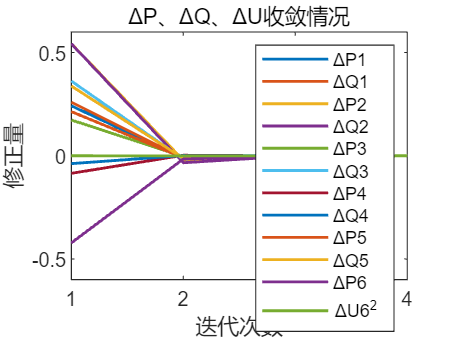


plot(dPQU_mat,'-','LineWidth',1.3);
xticks(0:1:circle_count+1);
title('ΔP、ΔQ、ΔU收敛情况');
xlabel('迭代次数');
ylabel('修正量');
legend({'ΔP1','ΔQ1','ΔP2','ΔQ2','ΔP3','ΔQ3','ΔP4','ΔQ4','ΔP5','ΔQ5','ΔP6','ΔU6^2'},'Location', 'northeast');